Utilizando el RST

Creamos el robot:

clear
robot = rigidBodyTree;

Creamos los eslabones (objetos sólidos):

body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');

Se crean las uniones entre los eslabones:

jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');

Se definen las MTH entre cada eslabón y se hae el ensamble:

%body1
tform1 = transl(0, 0, 0.67);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0.312, 0, 0)*trotx(-pi/2)*trotz(-pi/2);
setFixedTransform(jnt2,tform2);
%setFixedTransform(jnt2,dhparams(2,:),'dh'); 
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(1.075, 0, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0.225, 1.73, 0)*trotx(-pi/2);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 0)*trotx(pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0.215, 0)*trotx(-pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')

El robot es el siguiente:

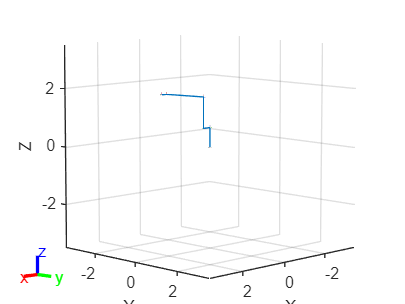

ans =   Axes (Primary) with properties:

             XLim: [-3.5000 3.5000]
             YLim: [-3.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure(1)
show(robot)

%viztree = interactiveRigidBodyTree(robot)
showdetails(robot)

--------------------
Robot: (7 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1              body1                   jnt1               revolute                   base(0)   body2(2)  
   2              body2                   jnt2               revolute                  body1(1)   body3(3)  
   3              body3                   jnt3               revolute                  body2(2)   body4(4)  
   4              body4                   jnt4               revolute                  body3(3)   body5(5)  
   5              body5                   jnt5               revolute                  body4(4)   body6(6)  
   6              body6                   jnt6               revolute                  body5(5)   endeffector(7)  
   7        endeffector        endeffector_jnt                  fixed 

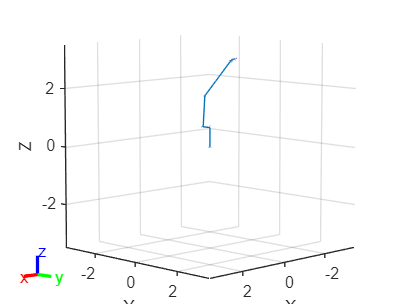

ans =   Axes (Primary) with properties:

             XLim: [-3.5000 3.5000]
             YLim: [-3.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



for i=1:2000
    config = randomConfiguration(robot);
    tform = getTransform(robot,config,'endeffector','base');
    x(i)=tform(1,4);
    y(i)=tform(2,4);
    z(i)=tform(3,4);
end
%config = randomConfiguration(robot)
%ik=inverseKinematics('rigidBodyTree',robot)
%tform = getTransform(robot,config,'endeffector','base')

figure(2)
show(robot,config)

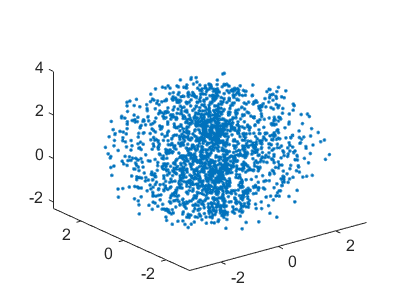

figure(3)
plot3(x(:),y(:),z(:),'.')

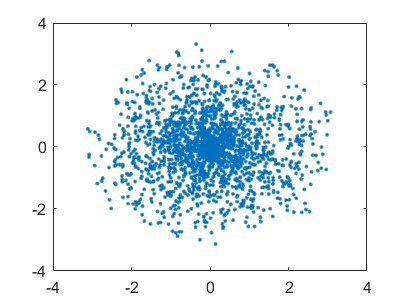

figure(4)
plot(x(:),y(:),'.')

Comparación entre RVC y RST:

Con RVC es muy fácil construir el robot a partir de los parámetros DH utilizando funciones simples como Link, .A y SerialLink. La visualización y el movimiento del robot es fácil utilizando este toolbox. Por otro lado, RST da muchas opciones para construir el robot, se puede hacer a partir de los parámetros DH, las MTH entre los sistemas coordenados o con la traslación y la posición inicial. RST necesita más funciones para construir el robot pues toca crear cada elemento sólido e irlo agregando al cuerpo principal uno por uno. La interacción con el robot usando RST es un poco más compleja pues no muestra tantas cosas como lo hace el RVC. 